### **OBC Calculation**

clear variables
close all
clc

First of all we define the physical parameters of our system:

particleDensity = 1 % n = N\L

particleDensity = 1

cutoff = 35 % In ``Hartree''

cutoff = 35

V0 = 0 % In ``Hartree''

V0 = 0

W = 0.2 % Width of V(x)

W = 0.2000

And some computational parameter:

step = 100;     % Accuracy of numerical integrals
dx   = 1/step;
basisDIM = 500; % Basis dimension

Thermodynamic Limit:

$L\to\infty$, $N\to\infty$ such that $N/L = n$ is constant. 

So we need a cycle over L values:

Lmin = 2;     %
Lmax = 10;   % Only even values <=> Spinless electrons
Lstep = 2;   %

poles = zeros(step,step,step);
residues = zeros(step,step,step);

for L = Lmin:Lstep:Lmax 
    
    N = particleDensity*L;

Then we build the crystal hamiltonian computing matrix elements$\{\langle \psi^0_n | K + V(x) | \psi^0_m\rangle\}$:    

    % Hamiltonian Matrix
    H = zeros(basisDIM,basisDIM);
    
    for n = 1:basisDIM
        for m = 1:basisDIM
            
            %% Kinetic (diagonal) part %%
            if n == m
                H(n,n) = eigenE0(n,L);
            end
            
            %% Periodic potential part 
            x = linspace(0,L,step*L);
            braUket = conj(psi0(x,n,L)).*psi0(x,m,L).*V(x,L,V0,W);
            H(n,m) = H(n,m) + sum(braUket)*dx;
        end
    end

And look for eigen values and vectors:

    [c,E] = eig(H,'vector');

So now we compute the Fermi Energy of the perturbed system:

    if mod(N,2) == 0
        nF = N/2;
    else
        nF = (N+1)/2;
    end
    EF = E(nF); EF

Resulting energy scheme is:

    if L == Lmax || L == Lmax - 1
        figure("Name",'OBC Energy Levels')
         for n = 1:length(E)
             yline(E(n),'color',[0, 0.4470, 0.7410]);
             hold on
         end
         yline(EF,'--','color', 'red','LineWidth', 1.5);
         ylabel('Atomic Units')
         ylim([5,53]);
         title(sprintf('OBC Energy Levels for N = %d',N));
         set(gca,'xtick',[]);
         set(gca, 'Box', 'on');
    end

## Geometrical Drude Weight

$D = 2v_\mathrm{F}$, with some care on what $v_\mathrm{F}$ is:

    if nF > 2
     % OBC Fermi velocity
        vF = (E(nF+1)-E(nF-1))/(2*(pi/L));
     % OBC Geometrical Drude Weight
        deltaL = L-Lmin;
        Dw(deltaL/Lstep + 1) = 2*vF/pi;
    end

## Kubo Poles and Residues

Now we proced with linear response evaluation (Kubo Formulae)

- First we build up wavefunctions:

     x = linspace(0,L,step*L);
     psi = zeros(length(x),basisDIM);
     for n = 1:basisDIM
          psi_x = zeros(1,length(x));
          for m = 1:basisDIM
              psi_x = psi_x + psi0(x,m,L) * c(m,n);
          end
          psi(:,n) = psi_x;
     end
     
     if L == Lmax
         figure("Name",'Crystal Wavefunctions')
         plot(x,V(x,L,V0,W),'color',[0.7,0.7,0.7], 'linewidth', 1.5); hold on
         for n = 1:3
            plot(x,V0*real(psi(:,n)), 'linewidth', 1.5);
         end
     end

- Then we apply the velocity operator $\hat{v} = i  \frac{\mathrm{d}}{\mathrm{d}x}$:

     vpsi = zeros(length(x),basisDIM);
     dpsi_dx = zeros(1,length(x));
     for n = 1:basisDIM
         dpsi_dx(1:(length(x)-1)) = diff(psi(:,n))/dx;
         dpsi_dx(length(x)) = dpsi_dx(length(x)-1); % Border Trick
         vpsi(:,n) = 1i * dpsi_dx;
     end
     
%      figure("Name",'Derivative of Crystal Wavefunctions')
%      plot(x,V(x, L,V0,W),'color',[0.5,0.5,0.5], 'linewidth', 2); hold on
%      for n = 1:5
%         plot(x,imag(vpsi(:,n)), 'linewidth', 1.5);
%      end

- So we can compute pole frequencies and residues:

     % Journey through all possible excited (many-body) states compatible with Pauli principle
     n = 1;
     w = zeros(basisDIM,basisDIM);
     res = zeros(basisDIM,basisDIM);
     while 1
         if n == nF
             break
         end
         m = nF;
         while 1
             dw = E(m)-E(n);
             if dw > cutoff || m > basisDIM
                 break
             end
             w(n,m) = dw; % Pole frequency
             braket_nm = conj(psi(:,n)).*vpsi(:,m);
             braket_mn = conj(vpsi(:,m)).*psi(:,n);
%              figure("Name",'Kubo Overlap')
%              plot(x,V(x, L,V0,W),'color',[0.5,0.5,0.5], 'linewidth', 2); hold on
%              plot(x,imag(braket_nm(:)), 'linewidth', 1.5);
%              plot(x,imag(braket_mn(:)), 'linewidth', 1.5);
             M1 = sum(braket_nm)*dx;
             M2 = sum(braket_mn)*dx;
             if abs(M1) < 0.001 || abs(M2) < 0.001
                 res(n,m) = 0;
             else
                  res(n,m) = 4*M1*M2/(dw*L);              
             end
              m = m+1;
         end
         n = n+1;
     end
     nMax = n;
     mMax = m;
     
     % Smart reshaffling:
     deltaL = L-Lmin;
     nPoles = zeros(1,mMax-1);
     nResidues = zeros(1,mMax-1);
     for n = 1:nF
         for m_n = 1:(mMax-n)
             m = n + m_n; % i.e. m-n = m_n ;)
             nPoles(m_n) = w(n,m);
             nResidues(m_n) = res(n,m);
         end
         poles(n, deltaL/Lstep+1, 1:length(nPoles)) = nPoles;
         residues(n, deltaL/Lstep+1, 1:length(nResidues)) = nResidues;
     end

EF = 1.2337

EF = 1.2337

EF = 1.2337

EF = 1.2337

EF = 1.2337

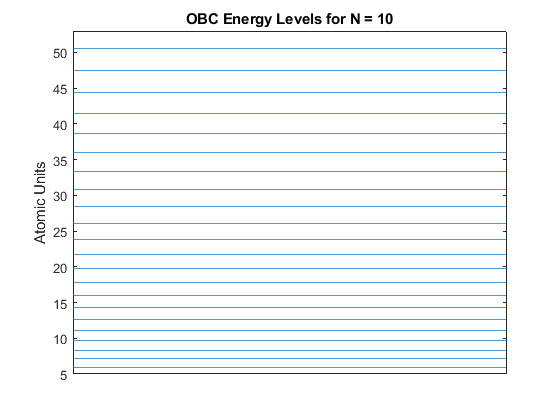

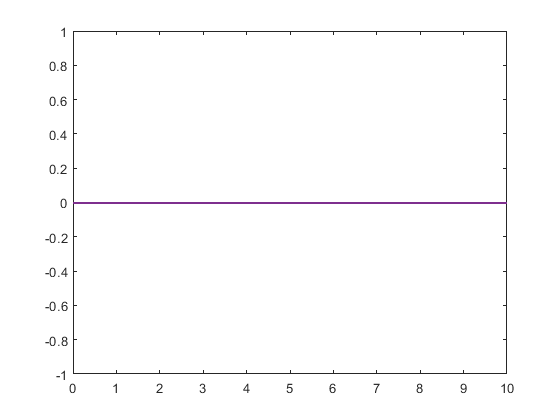

end

Drude Weight and F-sum:

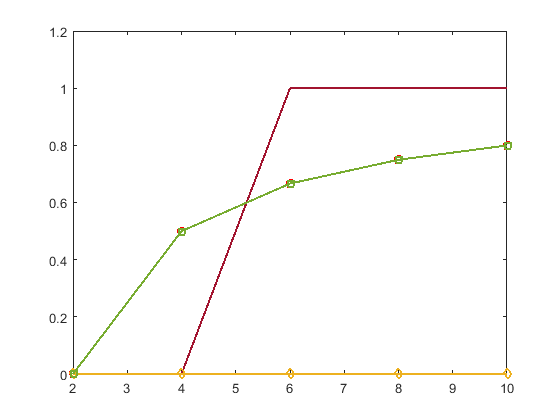

% Determing Treshold
spacing = zeros(1,basisDIM-1);
for n = 1:mMax
 spacing(n) = E(n+1) - E(n);
end
[gap,nV] = max(spacing);
nC = nV + 1;
Ev = E(nV);
Ec = E(nC);
w_th = (Ec + Ev)/2 - E(1);
w_th = 100;

% D-Sum, R-Sum and F-sum
Ls = Lmin:Lstep:Lmax;
for L = Ls
    deltaL = L-Lmin;
    L_freq = poles(:,deltaL/Lstep+1,:);
    L_res = residues(:,deltaL/Lstep+1,:);
    F_res = L_res(L_freq > 0);
    D_res = L_res(L_freq < w_th & L_freq > 0);
    D_freq = L_freq(L_freq < w_th & L_freq > 0);
    R_res = L_res(L_freq > w_th & L_freq > 0);
    R_freq = L_freq(L_freq > w_th & L_freq > 0);
    D(deltaL/Lstep+1) = sum(D_res);
    R(deltaL/Lstep+1) = sum(R_res);
    FSum(deltaL/Lstep+1) = sum(F_res);
    D_SWM(deltaL/Lstep+1) = sum(D_res./D_freq);
    R_SWM(deltaL/Lstep+1) = sum(R_res./R_freq);
end
red = [1, 0, 0];
blood = [0.6350, 0.0780, 0.1840];
green = [0.4660, 0.6740, 0.1880];
orange = [0.9290, 0.6940, 0.1250];
figure("Name",'F-Sum Analysis')
plot(Ls,D,'o-','color',red,'LineWidth',1.5);
hold on
plot(Ls,Dw,'-','color',blood,'LineWidth',1.5);
plot(Ls,R,'d-','color',orange,'LineWidth',1.5);
plot(Ls,FSum,'s-','color',green,'LineWidth',1.5);

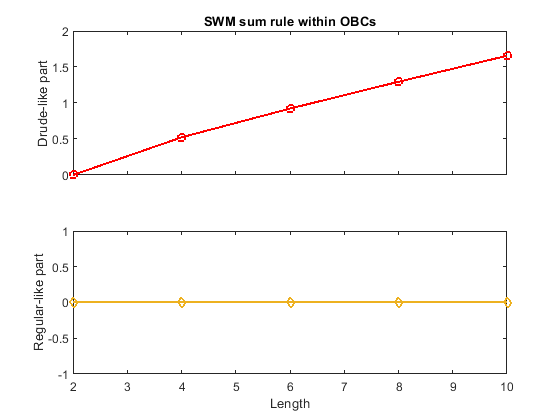


figure("Name",'SWM sum rule')
% Create subplots
subplot(2,1,1)
plot(Ls,D_SWM,'o-','color',red,'LineWidth',1.5); 
title('SWM sum rule within OBCs')
ylabel('Drude-like part')
xticklabels({})
subplot(2,1,2)
plot(Ls,R_SWM,'d-','color',orange,'LineWidth',1.5);
%title('Regular-like part')
xlabel('Length')
ylabel('Regular-like part')

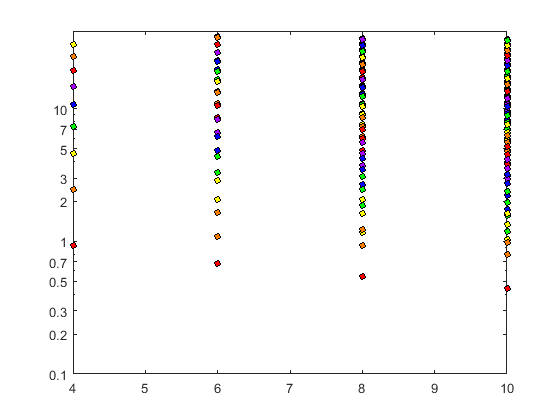

%sgt = sgtitle('SWM sum rule within OBCs');
%sgt.FontSize = 20;

figure("Name",'Pole-Frequency Analysis')
Ls = Lmin:Lstep:Lmax;
for n = 1:nMax
    CM = prism(mMax-n);
    for m_n = 1:(mMax-n)
        freqs = poles(n,:,m_n);
        Dfreqs = freqs(freqs < w_th & freqs > 0);
        DLs = Ls(freqs < w_th & freqs > 0);
        Rfreqs = freqs(freqs > w_th & freqs > 0);
        RLs = Ls(freqs > w_th & freqs > 0);
        plot(RLs,Rfreqs,'o','MarkerEdgeColor', 'black','MarkerFaceColor',[0.7,0.7,0.7],'MarkerSize', 5);
        hold on
        plot(DLs,Dfreqs,'o','MarkerEdgeColor', 'black','MarkerFaceColor',CM(m_n,:), 'MarkerSize', 5);
        yline(w_th,'--');
        yticks([0.1 0.2 0.3 0.5 0.7 1 2 3 5 7 10])
        set(gca, 'Ylim', [0.1,cutoff*1.1]);
        set(gca, 'YScale', 'log');
        set(gca, 'Box', 'on');
    end
end

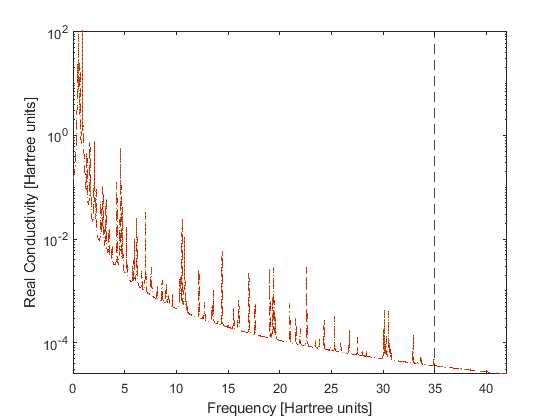


figure("Name", 'OBC Conductivity')
z = linspace(0,1.2*cutoff,step*10);
Gz = zeros(1,length(z));
Dz = zeros(1,length(z));
Rz = zeros(1,length(z));
eta = 0.005; %1*EF/Lmax;
freqs = poles(poles~=0);
resds = residues(poles~=0);
minRes = min(resds(resds~=0));
maxRes = max(resds(resds~=0));
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        Gz = Gz + 1i*Res.*(1./(dw.*(z-dw+1i*eta))+1./(dw.*(z+dw+1i*eta)));
        if dw < w_th
            Dz = Dz + 1i*Res.*(1./(dw.*(z-dw+1i*eta))+1./(dw.*(z+dw+1i*eta)));
        else
            Rz = Rz + 1i*Res.*(1./(dw.*(z-dw+1i*eta))+1./(dw.*(z+dw+1i*eta)));
        end
end
plot(z,real(Dz),'--','LineWidth', 1, 'color', red); hold on
plot(z,real(Rz),'LineWidth', 1, 'color', orange);
plot(z,real(Gz),':','LineWidth', 1, 'color', green);
maxCond = max(real(Dz));
minCond = min(real(Rz));
% for n = 1:length(freqs)
%         dw = freqs(n);
%         Res = resds(n);
%         plot([dw,dw],[minCond,maxCond],'-','LineWidth', 1, 'color', [0 0 0 0.1]); hold on
% end
xline(w_th,'-.','color', 'black');
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
set(gca,'Ylim',[minCond,maxCond]);
set(gca,'Yscale','log')
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')

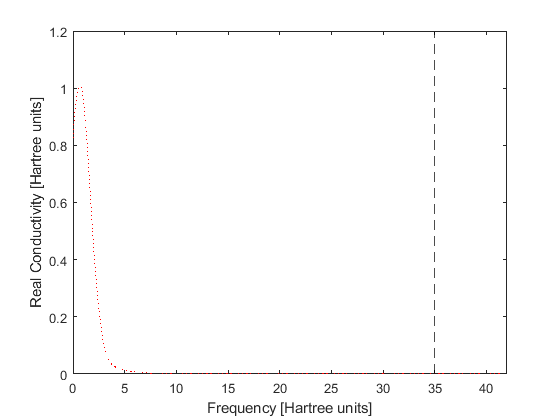


figure("Name", 'OBC Conductivity [GAUSSIAN SMEARING]')
sigma = 1; 
z = linspace(0,1.2*cutoff,step*10);
Gz = zeros(1,length(z));
Dz = zeros(1,length(z));
Rz = zeros(1,length(z));
freqs = poles(poles~=0);
resds = residues(poles~=0);
minRes = min(resds(resds~=0));
maxRes = max(resds(resds~=0));
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        if dw > w_th
        Gz = Gz + 1/(sigma*sqrt(2*pi)).*Res.*exp(-0.5.*(z-dw/sigma).^2);
        else
        Dz = Dz + 1/(sigma*sqrt(2*pi)).*Res.*exp(-0.5.*(z-dw/sigma).^2);  
        end
end
%plot(z,real(Gz),':','LineWidth', 1, 'color', orange); hold on
plot(z,real(Dz),':','LineWidth', 1, 'color', red); 
%plot(z,real(Dz+Gz),':','LineWidth', 1, 'color', green); 
maxCond = unique(max(real(Dz)));
minCond = unique(min(real(Gz)));
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
%set(gca,'Ylim',[minCond,maxCond]);
%set(gca,'Yscale','log')
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')

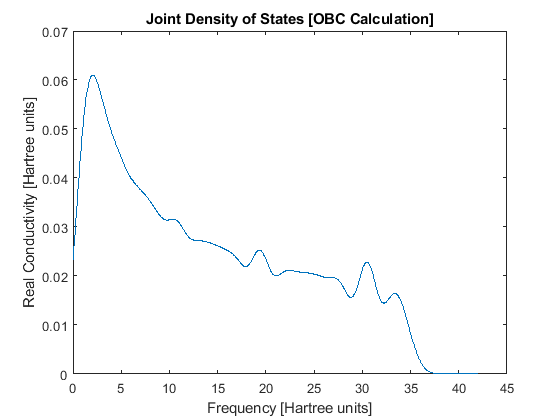


figure("Name",'Joint DOS OBC')
sigma = 1; 
z = linspace(0,1.2*cutoff,step*10);
jDOS = zeros(1,length(z));
Norm = 0;
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        if dw < cutoff
                 jDOS = jDOS + 1/(sigma*sqrt(2*pi)).*exp(-0.5.*(z-dw/sigma).^2);
                 Norm = Norm + 1;
        end
end
plot(z,jDOS/Norm,'LineWidth', 1); 
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')
title('Joint Density of States [OBC Calculation]')

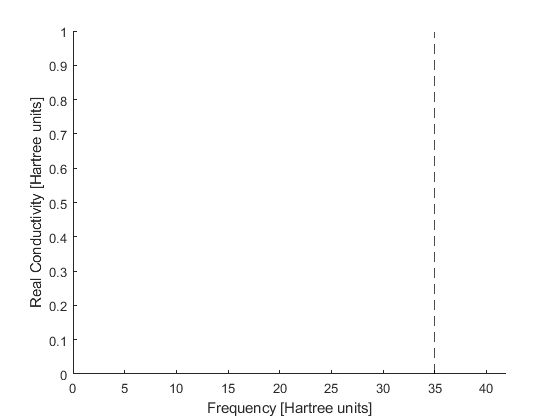


% figure("Name",'Unsmeared Conductivity LOG')
% % for n = 1:length(freqs)
% %         dw = freqs(n);
% %         Res = resds(n);
% %         plot([dw,dw],[minRes,maxRes],'-','LineWidth', 1, 'color', [0 0 0 0.1]); hold on
% % end
% for n = 1:length(freqs)
%         dw = freqs(n);
%         Res = resds(n);
%         if dw < w_th
%             plot([dw,dw],[minRes,Res],'-','LineWidth', 1, 'color', red); hold on
%         else
%             plot([dw,dw],[minRes,Res],'-','LineWidth', 1, 'color', orange);
%         end
% end
% xline(w_th,'-.','color', 'black');
% xline(cutoff,'--','color', 'black');
% set(gca,'Xlim',[0,1.2*cutoff]);
% set(gca,'Ylim',[minRes,maxRes]);
% set(gca,'Yscale','log')
% xlabel('Frequency [Hartree units]')
% ylabel('Real Conductivity [Hartree units]')

figure("Name",'Unsmeared Conductivity LIN')
% for n = 1:length(freqs)
%         dw = freqs(n);
%         Res = resds(n);
%         plot([dw,dw],[minRes,maxRes],'-','LineWidth', 1, 'color', [0 0 0 0.1]); hold on
% end
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        if dw < w_th
            % DO NOTHING!
        else
            plot([dw,dw],[0,Res],'-','LineWidth', 1, 'color', orange); hold on
        end
end
xline(w_th,'-.','color', 'black');
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
%set(gca,'Ylim',[0,maxRes]);
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')


figure("Name",'Pole-Frequency Spaghetti')
Ls = Lmin:Lstep:Lmax;
Dfreqs = [];
DLs = [];
Rfreqs = [];
RLs = [];
CM = prism(mMax-n);
for m_n = 1:(mMax-n)
    for  n = 1:nMax
        freqs = poles(n,:,m_n);
        Dfreqs = [Dfreqs,freqs(freqs < w_th & freqs > 0)];
        DLs = [DLs, Ls(freqs < w_th & freqs > 0)];
        Rfreqs = [Rfreqs, freqs(freqs > w_th & freqs > 0)];
        RLs = [RLs,Ls(freqs > w_th & freqs > 0)];
        plot(RLs,Rfreqs,'-','MarkerEdgeColor', 'black','MarkerFaceColor',[0.7,0.7,0.7],'MarkerSize', 5);
    end
        plot(DLs,Dfreqs,'-','MarkerEdgeColor', 'black','MarkerFaceColor',CM(m_n,:), 'MarkerSize', 5);
        yline(w_th,'--'); hold on
        yticks([0.1 0.2 0.3 0.5 0.7 1 2 3 5 7 10])
        set(gca, 'Ylim', [0.1,cutoff*1.1]);
        set(gca, 'YScale', 'log');
        set(gca, 'Box', 'on');
end


Imperturbed OBC eigenvalues $E_n$: 

function En = eigenE0(n,L)
         En = (pi^2 * n^2)/(2 * L^2);
end

Imperturbed OBC eigenfunctions $\psi^0_n(x)$: 

function psi0_n = psi0(x,n,L)
         A = sqrt(2/L); % Normalization
         psi0_n = A*sin(pi/L * n * x);
end

 Periodic potential $V(x)$ as a sum of Gaussians:

function U = V(x,L,V0,W)
         
         U = 0;
         for x_i = 0:L+1 
             U = U + V0*exp(-(x-x_i).^2 / W^2);                        
         end
end